%% resultados_IPC_C1_C2_figuras_memoria.m
% Comparación de casos base, IPC integral y PI-IPC
%
% Casos:
%   - Viento constante 16 m/s
%   - Viento turbulento 16 m/s
%
% Controladores:
%   - Base
%   - Controlador 1: IPC integral
%   - Controlador 2: PI-IPC
%
% Ventana de análisis:
%   t >= 500 s
%
% Salida:
%   Resultados/Figuras_Memoria/IPC_C1_C2

clear; clc; close all;

%% Rutas

rootDir = fullfile(getenv('USERPROFILE'), 'Desktop', 'TFM_OpenFast');

matlabDir = fullfile(rootDir, 'Matlab');
addpath(genpath(matlabDir));

if isempty(which('ReadFASTbinary'))

    d = dir(fullfile(rootDir, '**', 'ReadFASTbinary.m'));

    if isempty(d)
        error('No se encuentra ReadFASTbinary.m dentro de TFM_OpenFast.');
    else
        addpath(genpath(d(1).folder));
        fprintf('ReadFASTbinary añadido desde:\n%s\n', fullfile(d(1).folder, d(1).name));
    end
end

outFigDir = fullfile(rootDir, 'Resultados', 'Figuras_Memoria', 'IPC_C1_C2');

if ~exist(outFigDir, 'dir')
    mkdir(outFigDir);
end

%% Configuración de análisis

tTrans = 500;
tZoom  = [500 620];

mDEL   = 10;
NeqDEL = 1e6;

pitchRateMax_deg_s = 8;   % velocidad de pitch usada para normalizar NAT

%% Definición de casos

casos = struct([]);

% ==========================
% Viento constante
% ==========================

casos(1).escenario = "Constante";
casos(1).controlador = "Base";
casos(1).tag = "Base_const";
casos(1).dir = fullfile(rootDir, 'Resultados', 'CasoA_v16_constante');

casos(2).escenario = "Constante";
casos(2).controlador = "IPC integral";
casos(2).tag = "C1_const";
casos(2).dir = fullfile(rootDir, 'Resultados', 'Controlador1_v4_KI3e7_Sat05_CasoA_v16_constante');

casos(3).escenario = "Constante";
casos(3).controlador = "PI-IPC";
casos(3).tag = "C2_const";
casos(3).dir = fullfile(rootDir, 'Resultados', 'Controlador2_v4_KPneg1e-6_KI3e-7_CasoA_v16_constante');

% ==========================
% Viento turbulento
% ==========================

casos(4).escenario = "Turbulento";
casos(4).controlador = "Base";
casos(4).tag = "Base_turb";
casos(4).dir = fullfile(rootDir, 'Resultados', 'CasoB_v16_turbulento');

casos(5).escenario = "Turbulento";
casos(5).controlador = "IPC integral";
casos(5).tag = "C1_turb";
casos(5).dir = fullfile(rootDir, 'Resultados', 'Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento');

casos(6).escenario = "Turbulento";
casos(6).controlador = "PI-IPC";
casos(6).tag = "C2_turb";
casos(6).dir = fullfile(rootDir, 'Resultados', 'Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento');

%% Localizar archivos .outb

for i = 1:numel(casos)

    d = [];

    if exist(casos(i).dir, 'dir')
        d = dir(fullfile(casos(i).dir, '**', '*.outb'));
    end

    if isempty(d)
        error('No se encuentra archivo .outb en la carpeta:\n%s', casos(i).dir);
    end

    casos(i).outb = fullfile(d(1).folder, d(1).name);

    fprintf('\n%s | %s\n%s\n', casos(i).escenario, casos(i).controlador, casos(i).outb);
end


Constante | Base
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb

Constante | IPC integral
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb

Constante | PI-IPC
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador2_v4_KPneg1e-6_KI3e-7_CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb

Turbulento | Base
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb

Turbulento | IPC integral
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb

Turbulento | PI-IPC
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb



%% Lectura de señales

for i = 1:numel(casos)

    tmp = leerCasoOpenFAST(casos(i).outb, casos(i).escenario, casos(i).controlador, tTrans);

    if i == 1
        S = repmat(tmp, numel(casos), 1);
    else
        tmp = orderfields(tmp, S(1));
        S(i) = tmp;
    end
end

Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 18:11:56 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".
Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 15-Aug-2026 at 22:47:52 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; Hy


%% Cálculo de métricas

tablaIPC_abs = table();

for i = 1:numel(S)

    fila = table();

    fila.Escenario = string(S(i).escenario);
    fila.Controlador = string(S(i).controlador);
    fila.Tiempo_analisis_s = max(S(i).t) - min(S(i).t);

    fila.Mean_GenPwr_MW = mean(S(i).GenPwr_MW, 'omitnan');
    fila.Std_GenPwr_MW  = std(S(i).GenPwr_MW, 'omitnan');

    fila.Mean_RotSpeed_rpm = mean(S(i).RotSpeed_rpm, 'omitnan');
    fila.Std_RotSpeed_rpm  = std(S(i).RotSpeed_rpm, 'omitnan');

    fila.Mean_BldPitch_deg = mean(S(i).BldPitchMean_deg, 'omitnan');
    fila.Std_BldPitch_deg  = std(S(i).BldPitchMean_deg, 'omitnan');

    fila.RMS_PtfmPitch_deg = rmsDemean(S(i).PtfmPitch_deg);
    fila.RMS_PtfmSurge_m   = rmsDemean(S(i).PtfmSurge_m);

    fila.DEL_RootMyb1_MNm = calcDEL(S(i).RootMyb1_MNm, mDEL, NeqDEL);
    fila.DEL_RootMyb2_MNm = calcDEL(S(i).RootMyb2_MNm, mDEL, NeqDEL);
    fila.DEL_RootMyb3_MNm = calcDEL(S(i).RootMyb3_MNm, mDEL, NeqDEL);

    fila.DEL_RootMyb_mean_MNm = mean([ ...
        fila.DEL_RootMyb1_MNm, ...
        fila.DEL_RootMyb2_MNm, ...
        fila.DEL_RootMyb3_MNm], 'omitnan');

    fila.RMS_Mtilt_MNm = rmsDemean(S(i).Mtilt_MNm);
    fila.RMS_Myaw_MNm  = rmsDemean(S(i).Myaw_MNm);

    fila.RMS_IPC_pitch_deg = calcRMS_IPC(S(i).BldPitch_deg);
    fila.Max_IPC_pitch_deg = calcMax_IPC(S(i).BldPitch_deg);

    fila.NAT_pitch_total_pct = calcNAT(S(i).BldPitch_deg, S(i).t, pitchRateMax_deg_s);
    fila.NAT_IPC_pitch_pct   = calcNAT(calcPitchIPC(S(i).BldPitch_deg), S(i).t, pitchRateMax_deg_s);

    tablaIPC_abs = [tablaIPC_abs; fila];
end

disp("=== TABLA ABSOLUTA IPC ===");

=== TABLA ABSOLUTA IPC ===


disp(tablaIPC_abs);

     Escenario       Controlador      Tiempo_analisis_s    Mean_GenPwr_MW    Std_GenPwr_MW    Mean_RotSpeed_rpm    Std_RotSpeed_rpm    Mean_BldPitch_deg    Std_BldPitch_deg    RMS_PtfmPitch_deg    RMS_PtfmSurge_m    DEL_RootMyb1_MNm    DEL_RootMyb2_MNm    DEL_RootMyb3_MNm    DEL_RootMyb_mean_MNm    RMS_Mtilt_MNm    RMS_Myaw_MNm    RMS_IPC_pitch_deg    Max_IPC_pitch_deg    NAT_pitch_total_pct    NAT_IPC_pitch_pct
    ____________    ______________    _________________    ______________    _____________    _________________    __


%% Tabla de variación porcentual respecto al base de cada escenario

varsPct = [
    "Mean_GenPwr_MW"
    "Std_GenPwr_MW"
    "Mean_RotSpeed_rpm"
    "Std_RotSpeed_rpm"
    "Mean_BldPitch_deg"
    "Std_BldPitch_deg"
    "RMS_PtfmPitch_deg"
    "RMS_PtfmSurge_m"
    "DEL_RootMyb_mean_MNm"
    "RMS_Mtilt_MNm"
    "RMS_Myaw_MNm"
    "RMS_IPC_pitch_deg"
    "Max_IPC_pitch_deg"
    "NAT_pitch_total_pct"
    "NAT_IPC_pitch_pct"
];

tablaIPC_pct = table();

escenarios = unique(tablaIPC_abs.Escenario, 'stable');

for e = 1:numel(escenarios)

    esc = escenarios(e);

    idxBase = tablaIPC_abs.Escenario == esc & tablaIPC_abs.Controlador == "Base";

    if ~any(idxBase)
        error('No encuentro base para escenario %s', esc);
    end

    baseRow = tablaIPC_abs(idxBase,:);

    idxEsc = find(tablaIPC_abs.Escenario == esc);

    for ii = 1:numel(idxEsc)

        r = idxEsc(ii);

        fila = table();
        fila.Escenario = tablaIPC_abs.Escenario(r);
        fila.Controlador = tablaIPC_abs.Controlador(r);

        for v = 1:numel(varsPct)

            varName = varsPct(v);

            xCtrl = tablaIPC_abs.(varName)(r);
            xBase = baseRow.(varName)(1);

            if abs(xBase) < 1e-12
                pct = NaN;
            else
                pct = 100 * (xCtrl - xBase) / xBase;
            end

            fila.(varName + "_pct") = pct;
        end

        tablaIPC_pct = [tablaIPC_pct; fila];
    end
end

disp("=== VARIACIÓN PORCENTUAL RESPECTO AL BASE ===");

=== VARIACIÓN PORCENTUAL RESPECTO AL BASE ===


disp(tablaIPC_pct);

     Escenario       Controlador      Mean_GenPwr_MW_pct    Std_GenPwr_MW_pct    Mean_RotSpeed_rpm_pct    Std_RotSpeed_rpm_pct    Mean_BldPitch_deg_pct    Std_BldPitch_deg_pct    RMS_PtfmPitch_deg_pct    RMS_PtfmSurge_m_pct    DEL_RootMyb_mean_MNm_pct    RMS_Mtilt_MNm_pct    RMS_Myaw_MNm_pct    RMS_IPC_pitch_deg_pct    Max_IPC_pitch_deg_pct    NAT_pitch_total_pct_pct    NAT_IPC_pitch_pct_pct
    ____________    ______________    __________________    _________________    _____________________    ____________________    _____________________    ____________________    <

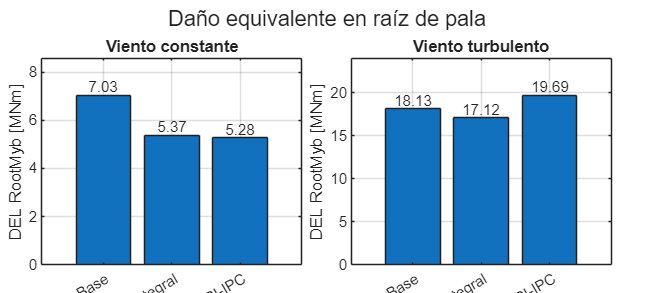


%% Guardar tablas

fileExcel = fullfile(outFigDir, 'tablas_IPC_C1_C2.xlsx');

writetable(tablaIPC_abs, fileExcel, 'Sheet', 'Valores_absolutos');
writetable(tablaIPC_pct, fileExcel, 'Sheet', 'Variacion_pct_base');

save(fullfile(outFigDir, 'tablas_IPC_C1_C2.mat'), 'tablaIPC_abs', 'tablaIPC_pct', 'S');

%% Ajustes gráficos generales

set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);
set(groot, 'defaultLegendFontSize', 10);

%% ============================================================
% FIGURA 1: DEL absoluto
% ============================================================

fig = figure('Color','w','Position',[100 100 1150 520]);
tl = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

controllers = ["Base", "IPC integral", "PI-IPC"];

for e = 1:numel(escenarios)

    esc = escenarios(e);

    nexttile;

    Y = getMetricByController(tablaIPC_abs, esc, controllers, "DEL_RootMyb_mean_MNm");

    cats = categorical(controllers);
    cats = reordercats(cats, controllers);

    b = bar(cats, Y);
    grid on; box on;
    ylabel('DEL RootMyb [MNm]');
    title("Viento " + lower(esc));

    addBarLabelsSingle(b, Y, 2);

    ylim([0, max(Y)*1.22]);
end

title(tl, 'Daño equivalente en raíz de pala');

guardarFigura(fig, outFigDir, 'ipc_DEL_absoluto');

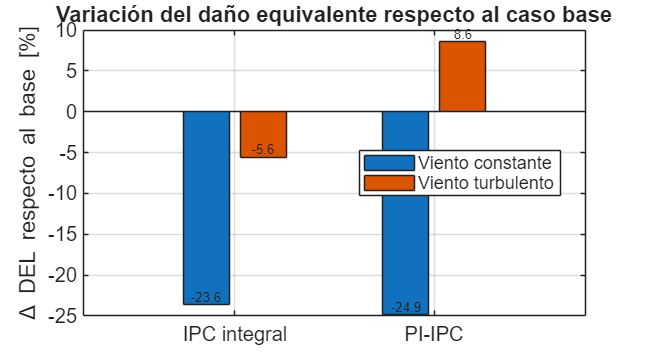


%% ============================================================
% FIGURA 2: variación porcentual DEL
% ============================================================

fig = figure('Color','w','Position',[100 100 950 520]);

controllersCtrl = ["IPC integral", "PI-IPC"];

Y = [
    getPct(tablaIPC_pct, "Constante", controllersCtrl, "DEL_RootMyb_mean_MNm_pct")';
    getPct(tablaIPC_pct, "Turbulento", controllersCtrl, "DEL_RootMyb_mean_MNm_pct")'
]';

cats = categorical(controllersCtrl);
cats = reordercats(cats, controllersCtrl);

b = bar(cats, Y, 'grouped');
grid on; box on;
yline(0, '--');
ylabel('\Delta DEL respecto al base [%]');
legend('Viento constante','Viento turbulento','Location','best');
title('Variación del daño equivalente respecto al caso base');

addBarLabelsGrouped(b, Y, 1);

guardarFigura(fig, outFigDir, 'ipc_DEL_variacion_pct');

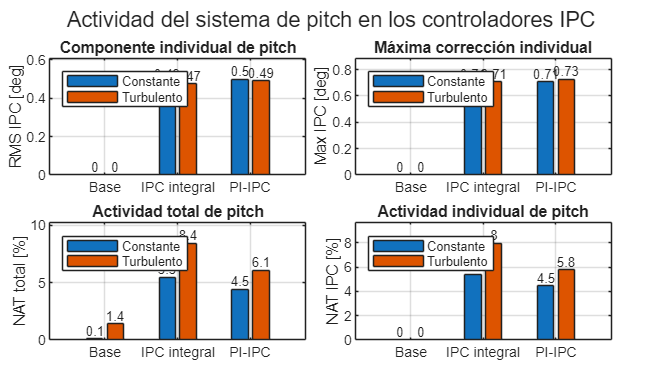


%% ============================================================
% FIGURA 3: actividad de pitch
% ============================================================

fig = figure('Color','w','Position',[100 100 1150 650]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

controllersAct = ["Base", "IPC integral", "PI-IPC"];

cats = categorical(controllersAct);
cats = reordercats(cats, controllersAct);

% ------------------------------------------------------------
% RMS IPC
% ------------------------------------------------------------

nexttile;

Y = [
    getMetricByController(tablaIPC_abs, "Constante",  controllersAct, "RMS_IPC_pitch_deg"), ...
    getMetricByController(tablaIPC_abs, "Turbulento", controllersAct, "RMS_IPC_pitch_deg")
];

b = bar(cats, Y, 'grouped');
grid on; box on;
ylabel('RMS IPC [deg]');
title('Componente individual de pitch');
legend('Constante','Turbulento','Location','northwest');

addBarLabelsGrouped(b, Y, 2);
ylim([0, max(Y(:))*1.22 + eps]);

% ------------------------------------------------------------
% Max IPC
% ------------------------------------------------------------

nexttile;

Y = [
    getMetricByController(tablaIPC_abs, "Constante",  controllersAct, "Max_IPC_pitch_deg"), ...
    getMetricByController(tablaIPC_abs, "Turbulento", controllersAct, "Max_IPC_pitch_deg")
];

b = bar(cats, Y, 'grouped');
grid on; box on;
ylabel('Max IPC [deg]');
title('Máxima corrección individual');
legend('Constante','Turbulento','Location','northwest');

addBarLabelsGrouped(b, Y, 2);
ylim([0, max(Y(:))*1.22 + eps]);

% ------------------------------------------------------------
% NAT total
% ------------------------------------------------------------

nexttile;

Y = [
    getMetricByController(tablaIPC_abs, "Constante",  controllersAct, "NAT_pitch_total_pct"), ...
    getMetricByController(tablaIPC_abs, "Turbulento", controllersAct, "NAT_pitch_total_pct")
];

b = bar(cats, Y, 'grouped');
grid on; box on;
ylabel('NAT total [%]');
title('Actividad total de pitch');
legend('Constante','Turbulento','Location','northwest');

addBarLabelsGrouped(b, Y, 1);
ylim([0, max(Y(:))*1.22 + eps]);

% ------------------------------------------------------------
% NAT IPC
% ------------------------------------------------------------

nexttile;

Y = [
    getMetricByController(tablaIPC_abs, "Constante",  controllersAct, "NAT_IPC_pitch_pct"), ...
    getMetricByController(tablaIPC_abs, "Turbulento", controllersAct, "NAT_IPC_pitch_pct")
];

b = bar(cats, Y, 'grouped');
grid on; box on;
ylabel('NAT IPC [%]');
title('Actividad individual de pitch');
legend('Constante','Turbulento','Location','northwest');

addBarLabelsGrouped(b, Y, 1);
ylim([0, max(Y(:))*1.22 + eps]);

title(tl, 'Actividad del sistema de pitch en los controladores IPC');

guardarFigura(fig, outFigDir, 'ipc_actividad_pitch');

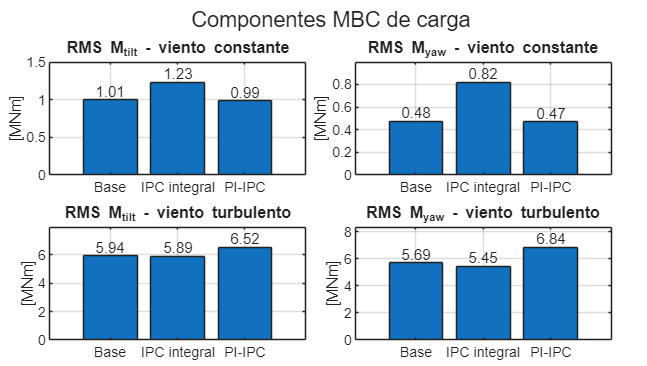


%% ============================================================
% FIGURA 4: RMS Mtilt y Myaw
% ============================================================

fig = figure('Color','w','Position',[100 100 1150 650]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

metricsMBC = ["RMS_Mtilt_MNm", "RMS_Myaw_MNm"];
titlesMBC  = ["RMS M_{tilt}", "RMS M_{yaw}"];

tileID = 1;

for e = 1:numel(escenarios)

    esc = escenarios(e);

    for m = 1:numel(metricsMBC)

        nexttile(tileID);

        Y = getMetricByController(tablaIPC_abs, esc, controllers, metricsMBC(m));

        cats = categorical(controllers);
        cats = reordercats(cats, controllers);

        b = bar(cats, Y);
        grid on; box on;
        ylabel('[MNm]');
        title(titlesMBC(m) + " - viento " + lower(esc));

        addBarLabelsSingle(b, Y, 2);

        ylim([0, max(Y)*1.22]);

        tileID = tileID + 1;
    end
end

title(tl, 'Componentes MBC de carga');

guardarFigura(fig, outFigDir, 'ipc_mbc_barras');

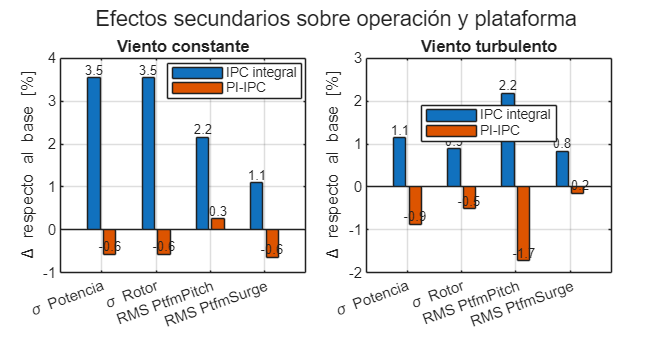


%% ============================================================
% FIGURA 5: variables operativas y plataforma, variación porcentual
% ============================================================

metricsSec = [
    "Std_GenPwr_MW_pct"
    "Std_RotSpeed_rpm_pct"
    "RMS_PtfmPitch_deg_pct"
    "RMS_PtfmSurge_m_pct"
];

namesSec = categorical({ ...
    '\sigma Potencia', ...
    '\sigma Rotor', ...
    'RMS PtfmPitch', ...
    'RMS PtfmSurge'});

namesSec = reordercats(namesSec, { ...
    '\sigma Potencia', ...
    '\sigma Rotor', ...
    'RMS PtfmPitch', ...
    'RMS PtfmSurge'});

fig = figure('Color','w','Position',[100 100 1150 600]);
tl = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

for e = 1:numel(escenarios)

    esc = escenarios(e);

    nexttile;

    Y = zeros(numel(metricsSec), numel(controllersCtrl));

    for c = 1:numel(controllersCtrl)
        for m = 1:numel(metricsSec)
            Y(m,c) = getPct(tablaIPC_pct, esc, controllersCtrl(c), metricsSec(m));
        end
    end

    b = bar(namesSec, Y, 'grouped');
    grid on; box on;
    yline(0, '--');
    ylabel('\Delta respecto al base [%]');
    title("Viento " + lower(esc));
    legend(controllersCtrl, 'Location','best');
    xtickangle(20);
    addBarLabelsGrouped(b, Y, 1);
end

title(tl, 'Efectos secundarios sobre operación y plataforma');

guardarFigura(fig, outFigDir, 'ipc_operacion_plataforma_pct');

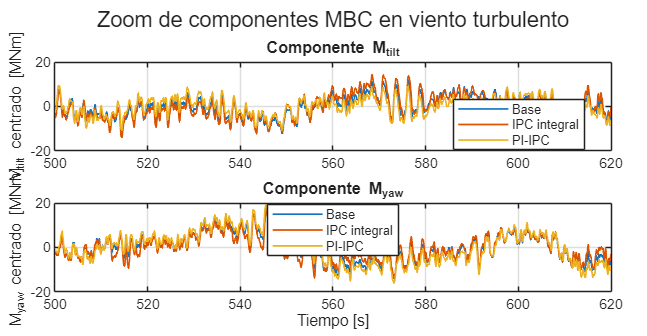


%% ============================================================
% FIGURA 6: zoom MBC turbulento
% ============================================================

SbaseT = getStructCase(S, "Turbulento", "Base");
Sc1T   = getStructCase(S, "Turbulento", "IPC integral");
Sc2T   = getStructCase(S, "Turbulento", "PI-IPC");

idxB  = SbaseT.t >= tZoom(1) & SbaseT.t <= tZoom(2);
idxC1 = Sc1T.t   >= tZoom(1) & Sc1T.t   <= tZoom(2);
idxC2 = Sc2T.t   >= tZoom(1) & Sc2T.t   <= tZoom(2);

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

nexttile;
plot(SbaseT.t(idxB), demeanSignal(SbaseT.Mtilt_MNm(idxB)), 'LineWidth', 1.0); hold on;
plot(Sc1T.t(idxC1),   demeanSignal(Sc1T.Mtilt_MNm(idxC1)),   'LineWidth', 1.0);
plot(Sc2T.t(idxC2),   demeanSignal(Sc2T.Mtilt_MNm(idxC2)),   'LineWidth', 1.0);
grid on; box on;
ylabel('M_{tilt} centrado [MNm]');
title('Componente M_{tilt}');
legend('Base','IPC integral','PI-IPC','Location','best');
xlim(tZoom);

nexttile;
plot(SbaseT.t(idxB), demeanSignal(SbaseT.Myaw_MNm(idxB)), 'LineWidth', 1.0); hold on;
plot(Sc1T.t(idxC1),   demeanSignal(Sc1T.Myaw_MNm(idxC1)),   'LineWidth', 1.0);
plot(Sc2T.t(idxC2),   demeanSignal(Sc2T.Myaw_MNm(idxC2)),   'LineWidth', 1.0);
grid on; box on;
ylabel('M_{yaw} centrado [MNm]');
xlabel('Tiempo [s]');
title('Componente M_{yaw}');
legend('Base','IPC integral','PI-IPC','Location','best');
xlim(tZoom);

title(tl, 'Zoom de componentes MBC en viento turbulento');

guardarFigura(fig, outFigDir, 'ipc_zoom_mbc_turbulento');

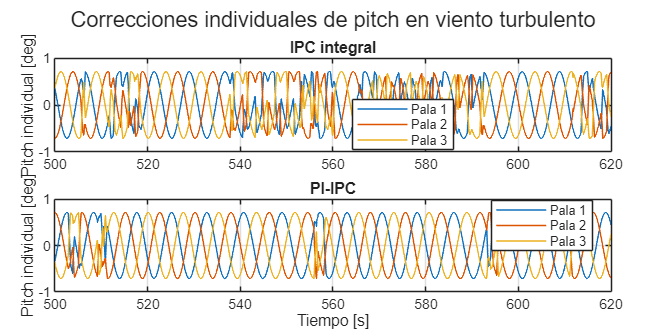


%% ============================================================
% FIGURA 7: zoom de pitch individual turbulento
% ============================================================

ipcC1 = calcPitchIPC(Sc1T.BldPitch_deg);
ipcC2 = calcPitchIPC(Sc2T.BldPitch_deg);

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

nexttile;
plot(Sc1T.t(idxC1), ipcC1(idxC1,1), 'LineWidth', 0.9); hold on;
plot(Sc1T.t(idxC1), ipcC1(idxC1,2), 'LineWidth', 0.9);
plot(Sc1T.t(idxC1), ipcC1(idxC1,3), 'LineWidth', 0.9);
grid on; box on;
ylabel('Pitch individual [deg]');
title('IPC integral');
legend('Pala 1','Pala 2','Pala 3','Location','best');
xlim(tZoom);

nexttile;
plot(Sc2T.t(idxC2), ipcC2(idxC2,1), 'LineWidth', 0.9); hold on;
plot(Sc2T.t(idxC2), ipcC2(idxC2,2), 'LineWidth', 0.9);
plot(Sc2T.t(idxC2), ipcC2(idxC2,3), 'LineWidth', 0.9);
grid on; box on;
ylabel('Pitch individual [deg]');
xlabel('Tiempo [s]');
title('PI-IPC');
legend('Pala 1','Pala 2','Pala 3','Location','best');
xlim(tZoom);

title(tl, 'Correcciones individuales de pitch en viento turbulento');

guardarFigura(fig, outFigDir, 'ipc_zoom_pitch_individual_turbulento');


fprintf('\nFiguras y tablas guardadas en:\n%s\n', outFigDir);


Figuras y tablas guardadas en:
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Figuras_Memoria\IPC_C1_C2



%% ============================================================
% FUNCIONES AUXILIARES
% ============================================================

function S = leerCasoOpenFAST(fileOutb, escenario, controlador, tTrans)

    [data, chanNames, ~] = ReadFASTbinary(fileOutb);

    if ischar(chanNames)
        chanNames = string(cellstr(chanNames));
    else
        chanNames = string(chanNames);
    end

    chanNames = strtrim(chanNames);
    cleanNames = matlab.lang.makeValidName(chanNames);

    get = @(name) getChannel(data, cleanNames, name);

    S.escenario = char(escenario);
    S.controlador = char(controlador);

    t = get('Time');
    idx = t >= tTrans;

    S.t = t(idx);

    S.GenPwr_MW = get('GenPwr');
    S.GenPwr_MW = S.GenPwr_MW(idx);

    if mean(abs(S.GenPwr_MW), 'omitnan') > 1000
        S.GenPwr_MW = S.GenPwr_MW / 1000;
    end

    S.RotSpeed_rpm = get('RotSpeed');
    S.RotSpeed_rpm = S.RotSpeed_rpm(idx);

    b1 = get('BldPitch1');
    b2 = get('BldPitch2');
    b3 = get('BldPitch3');

    S.BldPitch_deg = [b1(idx), b2(idx), b3(idx)];
    S.BldPitchMean_deg = mean(S.BldPitch_deg, 2, 'omitnan');

    S.PtfmPitch_deg = get('PtfmPitch');
    S.PtfmSurge_m   = get('PtfmSurge');

    S.PtfmPitch_deg = S.PtfmPitch_deg(idx);
    S.PtfmSurge_m   = S.PtfmSurge_m(idx);

    S.Azimuth_deg = get('Azimuth');
    S.Azimuth_deg = S.Azimuth_deg(idx);

    r1 = get('RootMyb1');
    r2 = get('RootMyb2');
    r3 = get('RootMyb3');

    S.RootMyb1_MNm = r1(idx);
    S.RootMyb2_MNm = r2(idx);
    S.RootMyb3_MNm = r3(idx);

    if mean(abs(S.RootMyb1_MNm), 'omitnan') > 1000
        S.RootMyb1_MNm = S.RootMyb1_MNm / 1000;
        S.RootMyb2_MNm = S.RootMyb2_MNm / 1000;
        S.RootMyb3_MNm = S.RootMyb3_MNm / 1000;
    end

    psi = deg2rad(S.Azimuth_deg);

    S.Mtilt_MNm = (2/3) .* ( ...
        S.RootMyb1_MNm .* cos(psi) + ...
        S.RootMyb2_MNm .* cos(psi + 2*pi/3) + ...
        S.RootMyb3_MNm .* cos(psi + 4*pi/3));

    S.Myaw_MNm = (2/3) .* ( ...
        S.RootMyb1_MNm .* sin(psi) + ...
        S.RootMyb2_MNm .* sin(psi + 2*pi/3) + ...
        S.RootMyb3_MNm .* sin(psi + 4*pi/3));
end

function y = getChannel(data, cleanNames, name)

    nameClean = matlab.lang.makeValidName(name);

    idx = find(strcmpi(cleanNames, nameClean), 1);

    if isempty(idx)
        error('No se encuentra el canal: %s', name);
    end

    y = data(:, idx);
end

function y = demeanSignal(x)

    y = x - mean(x, 'omitnan');
end

function y = rmsDemean(x)

    x = x - mean(x, 'omitnan');
    y = sqrt(mean(x.^2, 'omitnan'));
end

function DEL = calcDEL(x, m, Neq)

    x = x(:);
    x = x - mean(x, 'omitnan');

    rf = rainflow(x);

    if istable(rf)
        ranges = rf.Range;
        counts = rf.Count;
    else
        counts = rf(:,1);
        ranges = rf(:,2);
    end

    DEL = (sum(counts .* ranges.^m, 'omitnan') / Neq)^(1/m);
end

function betaIPC = calcPitchIPC(beta)

    betaCol = mean(beta, 2, 'omitnan');
    betaIPC = beta - betaCol;
end

function rmsIPC = calcRMS_IPC(beta)

    betaIPC = calcPitchIPC(beta);

    rmsBlade = sqrt(mean(betaIPC.^2, 1, 'omitnan'));
    rmsIPC = mean(rmsBlade, 'omitnan');
end

function maxIPC = calcMax_IPC(beta)

    betaIPC = calcPitchIPC(beta);
    maxIPC = max(abs(betaIPC), [], 'all', 'omitnan');
end

function NAT = calcNAT(beta, t, pitchRateMax_deg_s)

    dt = diff(t(:));

    if any(dt <= 0)
        error('El vector de tiempo no es estrictamente creciente.');
    end

    rate = abs(diff(beta) ./ dt);

    meanAbsRate = mean(rate, 1, 'omitnan');

    NAT = 100 * mean(meanAbsRate, 'omitnan') / pitchRateMax_deg_s;
end

function y = getMetricByController(T, escenario, controllers, metric)

    y = nan(numel(controllers),1);

    for i = 1:numel(controllers)

        idx = T.Escenario == string(escenario) & T.Controlador == string(controllers(i));

        if ~any(idx)
            error('No encuentro %s | %s', escenario, controllers(i));
        end

        y(i) = T.(metric)(idx);
    end
end

function y = getPct(T, escenario, controllers, metric)

    y = nan(numel(controllers),1);

    for i = 1:numel(controllers)

        idx = T.Escenario == string(escenario) & T.Controlador == string(controllers(i));

        if ~any(idx)
            error('No encuentro %s | %s', escenario, controllers(i));
        end

        y(i) = T.(metric)(idx);
    end
end

function Ssel = getStructCase(S, escenario, controlador)

    idx = find(strcmp(string({S.escenario}), string(escenario)) & ...
               strcmp(string({S.controlador}), string(controlador)), 1);

    if isempty(idx)
        error('No encuentro estructura para %s | %s', escenario, controlador);
    end

    Ssel = S(idx);
end

function addBarLabelsSingle(b, Y, ndigits)

    xtips = b.XEndPoints;
    ytips = b.YEndPoints;
    labels = string(round(Y, ndigits));

    text(xtips, ytips, labels, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','bottom', ...
        'FontSize',9);
end

function addBarLabelsGrouped(b, Y, ndigits)

    for k = 1:numel(b)

        xtips = b(k).XEndPoints;
        ytips = b(k).YEndPoints;

        labels = string(round(Y(:,k), ndigits));

        text(xtips, ytips, labels, ...
            'HorizontalAlignment','center', ...
            'VerticalAlignment','bottom', ...
            'FontSize',8);
    end
end

function guardarFigura(fig, outDir, name)

    exportgraphics(fig, fullfile(outDir, [name '.png']), 'Resolution', 300);
    savefig(fig, fullfile(outDir, [name '.fig']));
end